p = 0;
Cc = 0.61;
a = 0.6;
z1 = 5;
g = 0.81;
z2 = Cc .* a;

% (a)
az1 = a/z1

az1 = 0.1200

if (0.1 < az1) && (az1 < 0.2)
    p = z2 .* sqrt((2 .* g .* (z1 - z2))/(1 - (z2/z1).^2));
    fprintf('The flow rate per unit width is: %f\n', p)
else
    fprintf('Change the value of a = %f', a)
end

The flow rate per unit width is: 1.005503




% (b)

z1 = 5:0.25:15;
fprintf('z1             Q/b\n')

z1             Q/b



for i = 1:length(z1)
    q(i) = z2 .* sqrt((2 .* g .* (z1(i) - z2))/(1 - (z2/z1(i)).^2));
    fprintf('%d  %f      %f\n', i, z1(i), q(i))
end

1  5.000000      1.005503


2  5.250000      1.032011


3  5.500000      1.057865


4  5.750000      1.083110


5  6.000000      1.107788


6  6.250000      1.131933


7  6.500000      1.155580


8  6.750000      1.178757


9  7.000000      1.201492


10  7.250000      1.223808


11  7.500000      1.245727


12  7.750000      1.267270


13  8.000000      1.288456


14  8.250000      1.309302


15  8.500000      1.329822


16  8.750000      1.350033


17  9.000000      1.369948


18  9.250000      1.389579


19  9.500000      1.408937


20  9.750000      1.428035


21  10.000000      1.446882


22  10.250000      1.465487


23  10.500000      1.483860


24  10.750000      1.502010


25  11.000000      1.519944


26  11.250000      1.537669


27  11.500000      1.555193


28  11.750000      1.572522


29  12.000000      1.589664


30  12.250000      1.606622


31  12.500000      1.623405


32  12.750000      1.640016


33  13.000000      1.656461


34  13.250000      1.672745


35  13.500000      1.688872


36  13.750000      1.704847


37  14.000000      1.720674


38  14.250000      1.736358


39  14.500000      1.751901


40  14.750000      1.767308


41  15.000000      1.782582


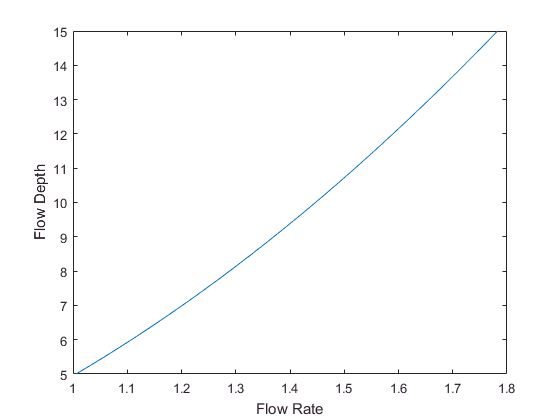


plot(q, z1)
xlabel('Flow Rate')
ylabel('Flow Depth')